# **Rotational Workspace for Cable-Driven Haptic Device (CDHD) in IMT. **

**Autor: Ing Tien Khaw**

## **Introduction**

This is a Matlab Live Script programme use to simulate the workspace by defining the parameter such as the:

- length 

- width

- height

- rod length

- wrench

- stepsize

- rotation angles  

By changing the parameter, the workspace of the CDHD will be influenced. This programme should be abole to deliver 3D figures which allow the viewer to have a better understanding about the influence of the parameter on the workspace of the CDHD. 

### Structure of the programme

This Live script contain of the maincode and also different live function. The general structure can be seen in the following figure. 

TODO: Flowchart of general workflow 

At the end of every calculation, the elapsed time will be showed. 

clear
clc
% close all
evaluation_timer=tic; %start the timer 

## Definition for frame, rod length & Region of Interest 

After considering different types of possible configurations with Falcon design, which is first inspired by [Kawamura](http://rraj.rsj-web.org/en_atcl/1366), due to its light weight, and simple design. The final design of CDHD has been showed in the following figure. From the tip of the endeffector (rod) to the corner of the frame, a total of 8 cables would be linked. The top of the frame has 4 winches (w1, w2, w3, and w4) at each corner and 4 cables. The lower side of the frame has 4 winches (w5, w6, w7, and w8) at each corner and 4 cables link to the bottom of the rod. 

 The region of interest (ROI): ROI has been defined as a cylinder with the diameter of 300 mm and height of 200 mm, which can be seen as the purple object in the figure. For the best configuration, the workspace from the haptice device should be able to cover the whole cylinder. 

Geometry of frame: The frame (red object in the figure) has been constructed in a square form, so that it could provide a symmetry workspace both in x- and y-direction. Therefore, ax and ay length would always be the same.

[Endeffector](https://en.wikipedia.org/wiki/Robot_end_effector), also known as mobile platform or manupulator: In this work, the mobile platform is a rigid rod made from carbon which has a defined length of 600 mm and diameter of 10 mm. At the bottom of the mobile platform, there will be a user interface gripper be integrated. The user will control the gripper to move the CDHD within the workspace. 

Degree of Freedom (DoF): The Falcon design with point shaped endeffector allowed a movement of 2R3T, resulted in 5 DoF. 

Trocar point: For the usage of haptic device in robot assisted surgery, the mobility of the Instrument would be limited to just 3 DoF, which can be seen in the following figure (TODO). Therefore, a virtual trocar point would be introduced to the CDHD. The trocar point would be exactly in the middle of the frame. 

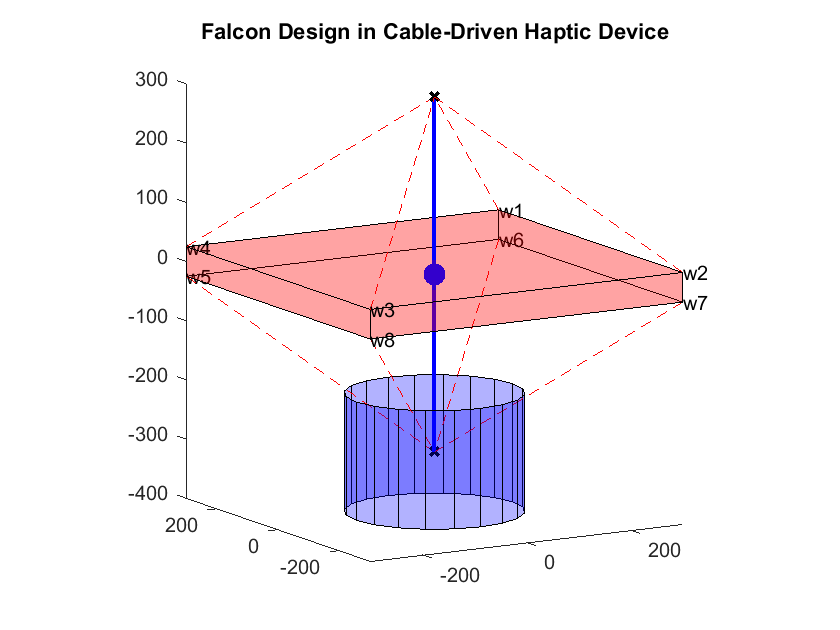

In this evaluation programm, there will be four cases to be choose.

- **standard**: Only a single configuration will be simulated. 4 Input variable must be given: ax_standard, ay_standard, az_standard and b_standard.  

- **ax**: For ax case, only the ax variable will be varied, based on the given ax_range. Therefore, az_standard and b_standard should have a fix values. 

- **az**: For az case, only the az variable will be varied, based on the given az_range. Therefore, ax_standard and b_standard should have a fix values.

- **b**: For b case, only the b variable will be varied, based on the given b_range. Therefore, ax_standard and az_standard should have a fix values.  

%%Define Parameter here 
noC = 8; %number of cable

%choose one to set a changing variable
ax_range = 300:50:600; %in mm
az_range = 0:50:300; %in mm
b_range = 300:50:600; %in mm

%the rest of the parameter will be fixed 
ax_standard = 600; %in mm (INPUT: length of ax) (predefined: always ax = ay) 
ay_standard = 600; %in mm (INPUT: length of ay) 
az_standard = 0; %in mm (INPUT: length of az)
 b_standard = 600; %in mm (INPUT: total length of rod)
 

After defining the parameter, function *SetupParameter.m *and *endeffector_parameter.m* will be called. 

The x_label will be marked with the name of the case. 

Elapsed time is 12.709508 seconds.


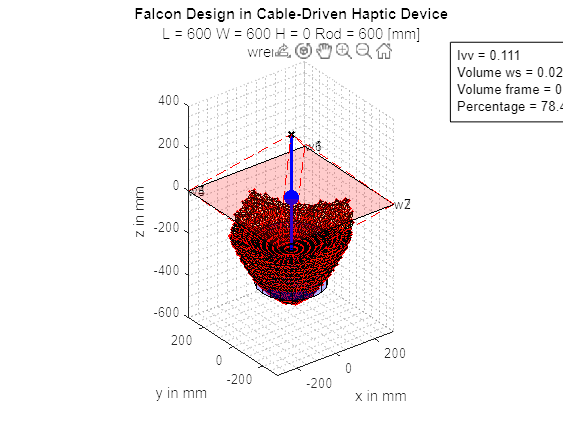

Parameter = "standard"; %Define changing parameter here 

switch Parameter
   case "standard"
        group = 0;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_standard);
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("standard [mm]"); %for plot
        loop_length = length(b_cell);
        zeros(length(b_cell),1);

    case "ax"
        group = 1;
        [a_cell] = SetupParameter(ax_range,ay_standard,az_standard);%variety
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("ax length [mm]"); %for plot
        loop_length = length(a_cell);

    case "az" 
        group = 2;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_range);%variety
        b_cell =  endeffector_parameter(b_standard);
        x_label = sprintf("az length [mm]"); %for plot
        loop_length = length(a_cell);
        
    case "b"
        group = 3;
        [a_cell] = SetupParameter(ax_standard,ay_standard,az_standard);
        b_cell =  endeffector_parameter(b_range); %variety
        x_label = sprintf("rod length [mm]"); %for plot
        loop_length = length(b_cell);

end

b = cell2mat(b_cell(1,1)); %standard parameter (it would be overwriten if its not standard)
a = cell2mat(a_cell(1,1)); %standard parameter (it would be overwriten if its not standard)

I_vv_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Volume_ws_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Volume_frame_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
Percentage_cell = cell(max(length(a_cell), length(b_cell)),1); %predefine for speed 
plot_x_axis = zeros(max(length(a_cell), length(b_cell)), 1); %predefine for speed 

for counter = 1 : loop_length
    switch Parameter     
        case "standard"
            a = cell2mat(a_cell(1,1));
            ax_value = a(1,1)*2; %times 2 because its only half od the length 
            ay_value = a(1,1)*2;
            az_value = a(3,1)*2;
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(1,1) = a(1,1)*2; 
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value) ' az = ' int2str(az_value)  ' rod length = ' int2str(b_value) ' [mm]'];

        case "ax"
            a = cell2mat(a_cell(counter,1)); %variety of parameter
            ax_value = a(1,1)*2; %times 2 because its only half od the length 
            ay_value = a(2,1)*2;
            az_value = a(3,1)*2;
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(counter,1) = a(1,1)*2; 
            txt = ['ay = ' int2str(ay_value) ' az = ' int2str(az_value)  ' rod length = ' int2str(b_value) ' [mm]']; 

        case "az"
            a = cell2mat(a_cell(counter,1)); %variety of parameter
            ax_value = a(1,1)*2; %times 2 because its only half od the length 
            ay_value = a(2,1)*2; 
            az_value = a(3,1)*2; 
            b_value = b_cell{1,1}(3)*2;
            plot_x_axis(counter,1) = a(3,1)*2; 
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value), ' rod length = ' int2str(b_value) ' [mm]']; 

        case "b"
            a = cell2mat(a_cell);
            ax_value = a(1,1)*2; %same as ax_standard
            ay_value = a(2,1)*2; %same as ax_standard
            az_value = a(3,1)*2; %same as ax_standard
            b = cell2mat(b_cell(counter,1)); %variety of parameter
            b_value = b(3,1)*2; %times two bcz only half of the length
            plot_x_axis(counter,1) = b_value; 
            txt = ['ax = ' int2str(ax_value) ' ay = ' int2str(ay_value), ' az = ' int2str(az_value) ' [mm]']; 

    end

        total_counter = 0; %reset counter  
        [workspace_trans_remove_OutL,vol_results_remove_OutL,cable_length_mat_cell_mat,w_p] = maincode_khaw(a,b,noC);
        
        % 4 specs analysis
        [I_vv,Volume_ws,Volume_frame] = evaluation_volume(vol_results_remove_OutL,ax_value,ay_value,b_value);
        [Percentage,Vol_point_in_ROI]  = Percentage_within_ROI(workspace_trans_remove_OutL,b_value);

        I_vv_cell{counter} = I_vv; 
        Volume_ws_cell{counter} = Volume_ws;
        Volume_frame_cell{counter} = Volume_frame;
        Percentage_cell{counter} = Percentage;  


[vol_results] = ws_plot_winner_khaw(workspace_trans_remove_OutL,a,b,noC,I_vv,Volume_ws*1e-9,Volume_frame*1e-9,Percentage,w_p);


% %save figure automatically
% path = 'D:\Masterarbeit\11_MATLAB_GIT\6. rotational workspace_khaw_Evaluation\figure\20220912';
% filename = "rotational_workspace_%d_%d_%d_%d_%d";
% filename_total = sprintf(filename,group, round(ax_value,0) ,round(ay_value,0), round(az_value,0), round(b_value,0));
% saveas(gcf,fullfile(path,filename_total),'fig');
% close(gcf)

end


I_vv_mat = cat(1,I_vv_cell{:});
Volume_ws_mat = cat(1,Volume_ws_cell{:});
Volume_frame_mat = cat(1,Volume_frame_cell{:});
Percentage_mat = cat(1, Percentage_cell{:});


% evaluation_plot(plot_x_axis,I_vv_mat,Volume_ws_mat,Volume_frame_mat,Percentage_mat,x_label,txt);

%save figure automatically
% path = 'D:\Masterarbeit\11_MATLAB_GIT\6. rotational workspace_khaw_Evaluation\figure\20220912';
% filename = "rotational_workspace_%d_%s";
% filename_total = sprintf(filename,group,x_label);
% saveas(gcf,fullfile(path,filename_total),'fig');
% close(gcf)


disp(strcat("Total execution time: ", num2str(toc(evaluation_timer)), "s"))

Total execution time: 16.2919s
